% adding cross section to 3D scatter
global i_cells cells x1 x2 y1 y2 z1 z2 lengths c1 c2 c x y z plot_range;
plot_range = [-100 100 -100 100 0 35];
i_cells =118;
for n = 1:4
    file_path = sprintf('data/Cells%d/%d.txt',n,i_cells);
    if n == 1
        cells = importdata(file_path);
    else
        cells = cat(1,cells,importdata(file_path));
    end
end
x1 = cells(:,4);
x2 = cells(:,7);
y1 = cells(:,5);
y2 = cells(:,8);
z1 = cells(:,6);
z2 = cells(:,9);
lengths = cells(:,10);
c1 = cells(:,27); % p age
c2 = cells(:,28); % q age

c = (c1 + c2)/2; % average pole age for cells
% average co-ordinates
x = (x1 + x2)/2;
y = (y1 + y2)/2;
z = (z1 + z2)/2;

global thickness dot_size;
dot_size =2;
thickness =5;

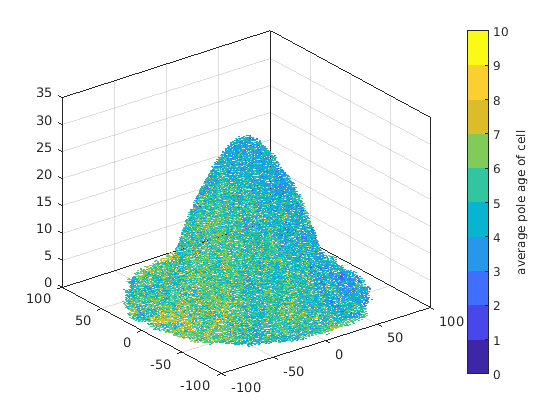

plt.age_plot()

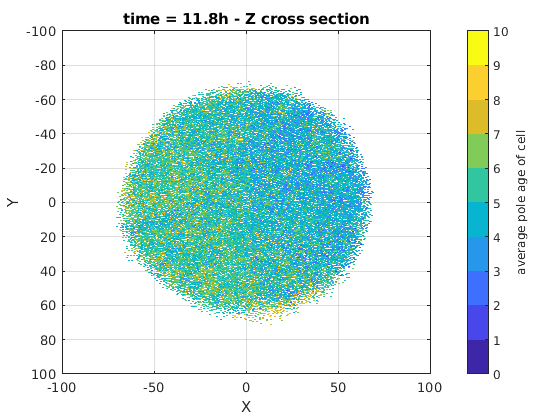

z_cut =2;
plt.age_plot('Z',z_cut)

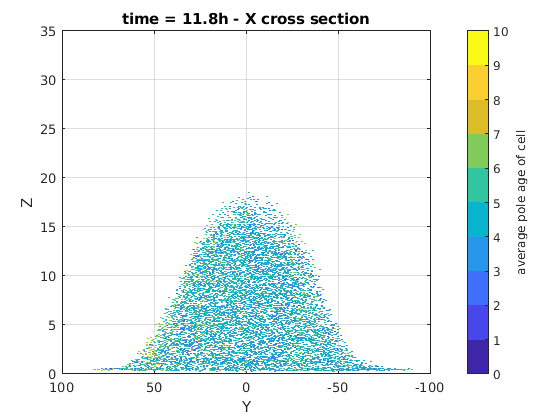

x_cut =38;
plt.age_plot('X',x_cut)

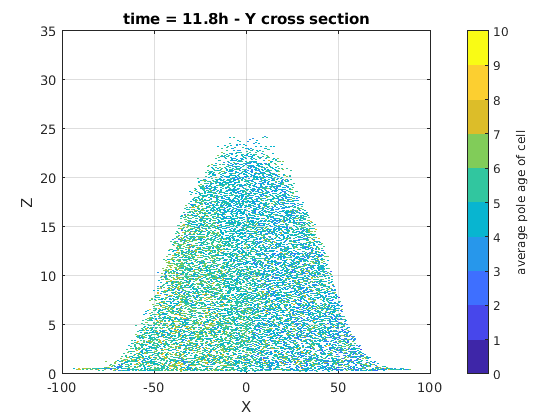

y_cut =22;
plt.age_plot('Y',y_cut)

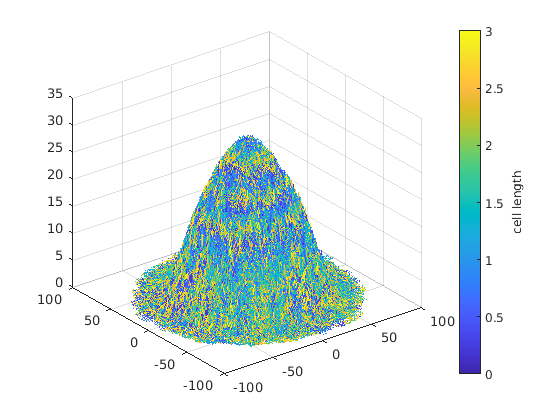

plt.length_plot()

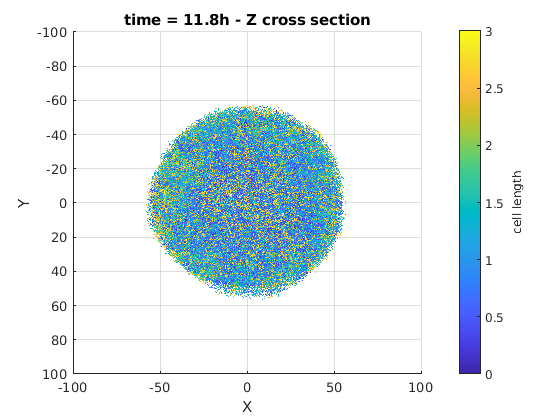

z_cut =8;
plt.length_plot('Z',z_cut)

%Using the "." will effectively perform element-by-element mathematical operations
r = sqrt(x.^2 + y.^2);
r_cut =35;
i = find(r<r_cut);

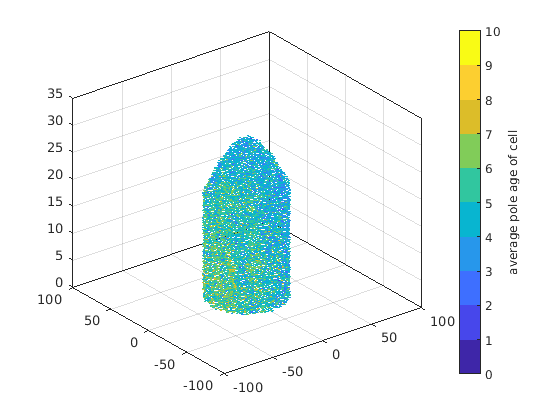

scatter3(x(i),y(i),z(i),dot_size,c(i), 'filled');
box on
h1=colorbar;
h1.Label.String = "average pole age of cell";
colormap(parula(10))
caxis([0, ceil(max(c))]);
axis(plot_range);

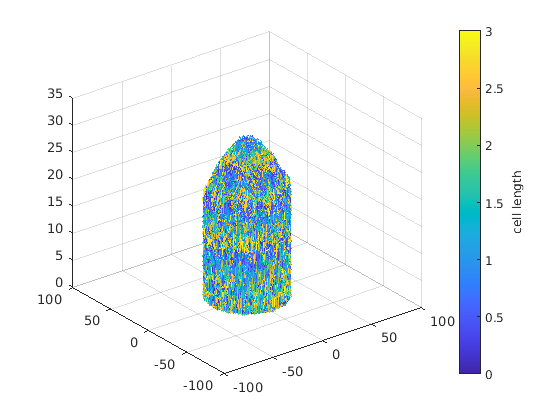


q = quiver3(x1(i),y1(i),z1(i),x2(i)-x1(i),y2(i)-y1(i),z2(i)-z1(i),'b', 'ShowArrowHead','off', 'Autoscale','off');

%// Get the current colormap

colormap default
caxis([floor(min(lengths(i))) ceil(max(lengths(i)))])
currentColormap = colormap(gca);

%// Now determine the color to make each arrow using a colormap
[~, ~, ind] = histcounts(lengths(i), size(currentColormap, 1));

%// Now map this to a colormap to get RGB
cmap = uint8(ind2rgb(ind(:), currentColormap) * 255);
cmap(:,:,4) = 255;
cmap = permute(repmat(cmap, [1 3 1]), [2 1 3]);

%// We repeat each color 2 times (using 1:2 below) because each tail has 2 vertices
set(q.Tail, ...
    'ColorBinding', 'interpolated', ...
    'ColorData', reshape(cmap(1:2,:,:), [], 4).');
h1 = colorbar;
h1.Label.String = 'cell length';
axis(plot_range);